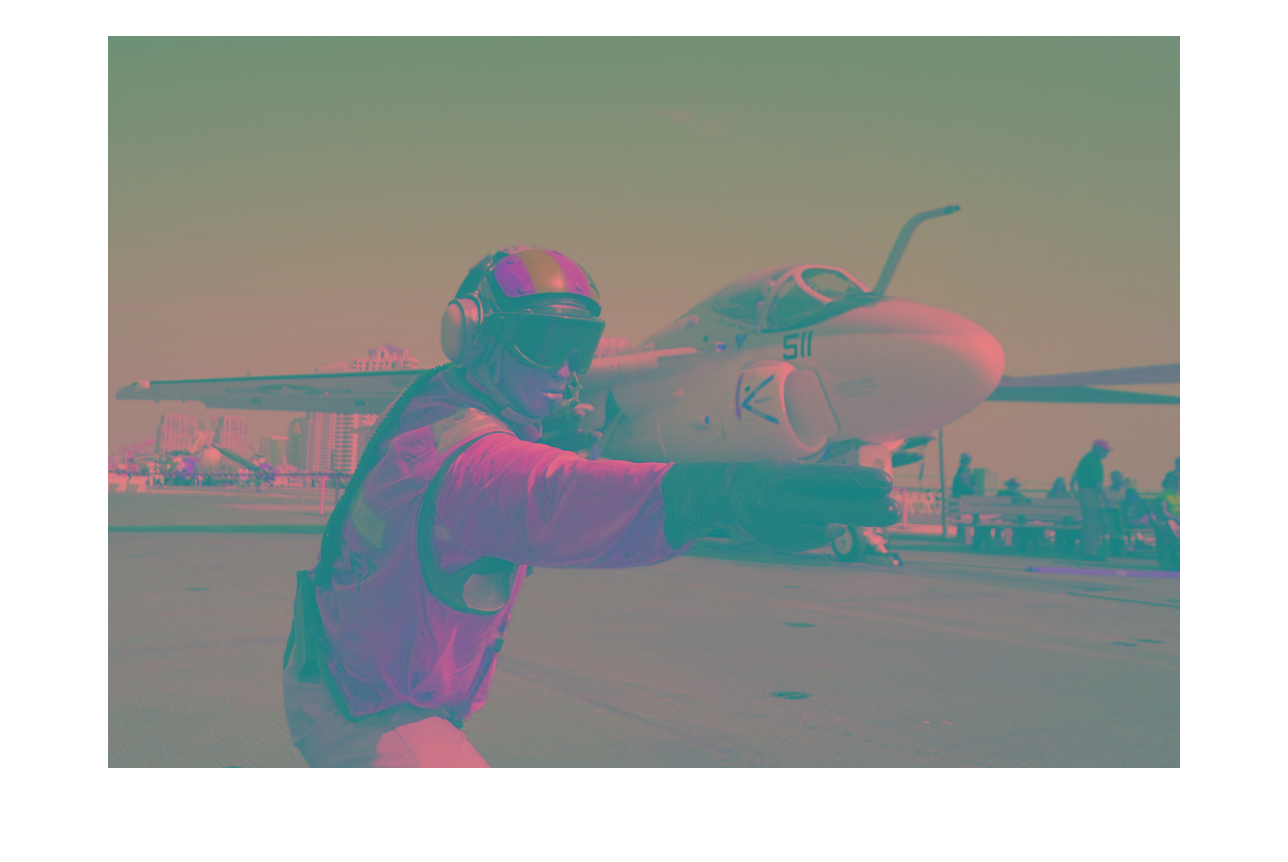

%convert the image to YUV type
[pilot] = imread('pilot.jpg');
%YUV should be value in [0,255]
pilot_YUV=rgb2ycbcr(pilot);
imshow(pilot_YUV);

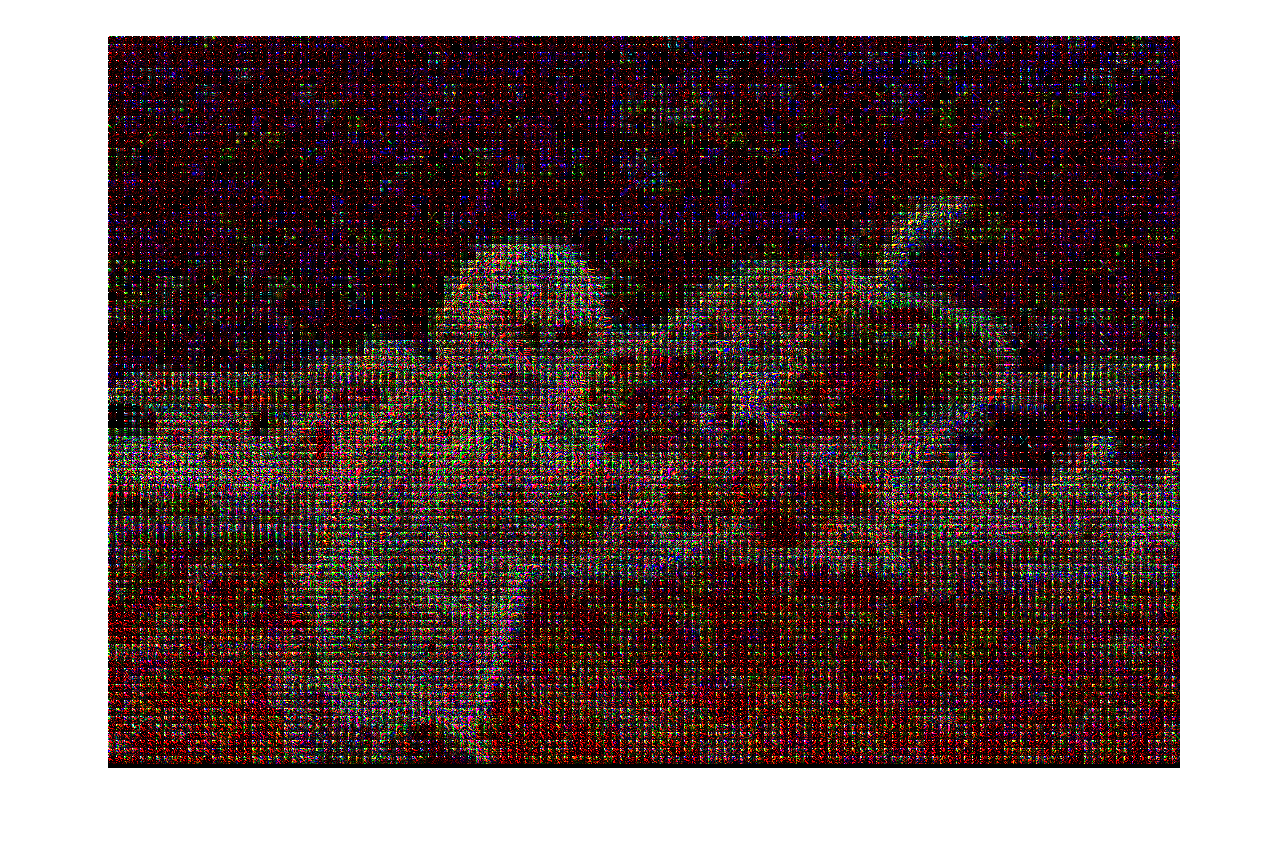


[row,col,channel]=size(pilot_YUV);
pilot_dct=zeros(row,col,channel);
pilot_qua=zeros(row,col,channel);
pilot_YUV_recover=zeros(row,col,channel);
pilot_encode=zeros(row,col,channel);
RLencode={[],[],[]};
DC_matrix={[],[],[]};

quatization_matrix=[
[16,11,10,16,24,40,51,61]
[12,12,14,19,26,58,60,55]
[14,13,16,24,40,57,69,56]
[14,17,22,29,51,87,80,62]
[18,22,37,56,68,109,103,77]
[24,35,55,64,81,104,113,92]
[49,64,78,87,103,121,120,101]
[72,92,95,98,112,100,103,99]];

%y=encode(quatization_matrix)
% slice each part into 8*8 matrix, do dct,quantization,encode
for i=1:row/8
    for j=1:col/8
        for k=1:channel
            downsample_pilot=pilot_YUV(8*i-7:8*i,8*j-7:8*j,k);
            % for each 8*8 input matrix apply dct
            pilot_dct(8*i-7:8*i,8*j-7:8*j,k)=dct2(downsample_pilot);
            %divide by quantization matrix
            pilot_qua(8*i-7:8*i,8*j-7:8*j,k)=round(pilot_dct(8*i-7:8*i,8*j-7:8*j,k)./quatization_matrix);
            %zigzag & Run length encode
            [DC,pilot_encode(8*i-7:8*i,8*j-7:8*j,k),code]=encode(pilot_qua(8*i-7:8*i,8*j-7:8*j,k));
            % for each channel, run length encode link into a vector, store each DC term in another array 
            DC_matrix{k}=[DC_matrix{k},DC];
            RLencode{k}=[RLencode{k},code];
        end
    end
end
imshow(pilot_dct);

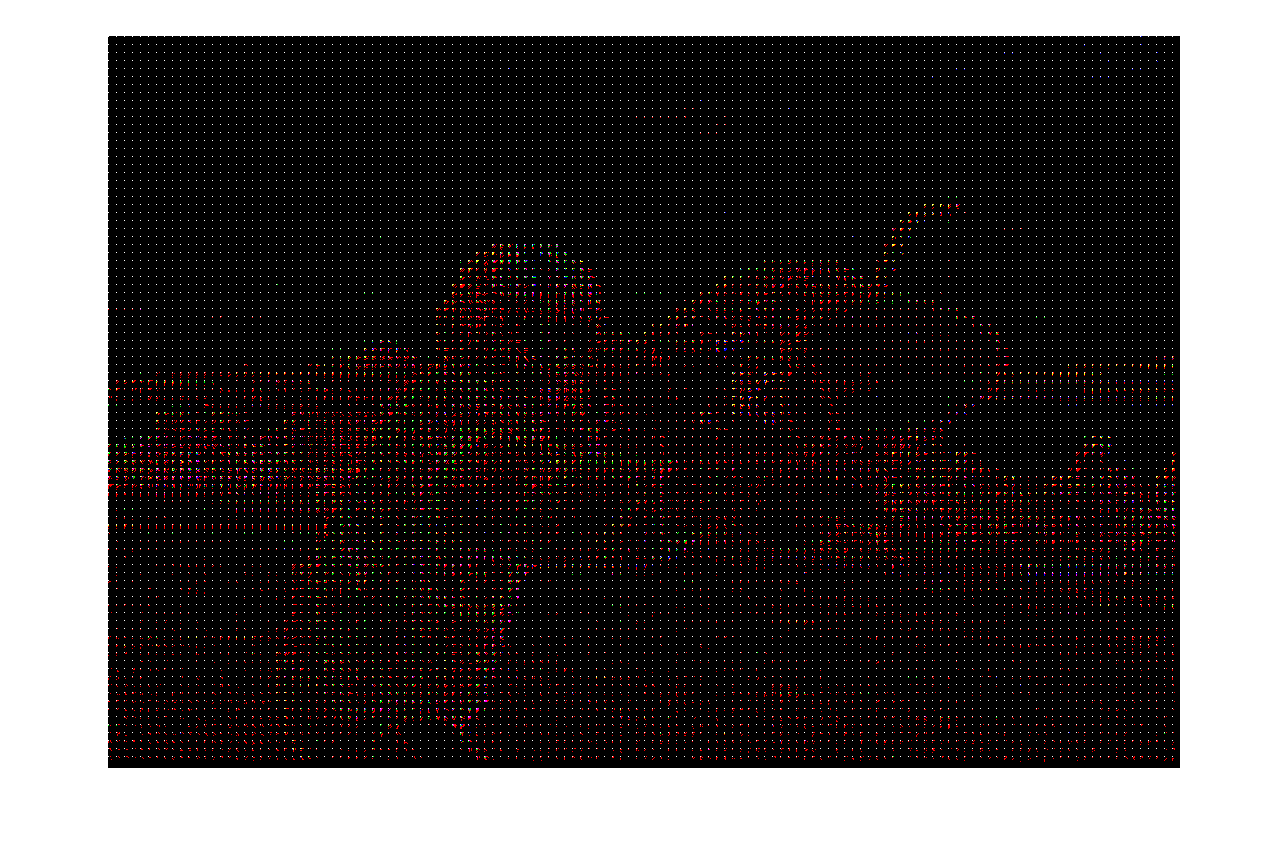

imshow(pilot_qua);

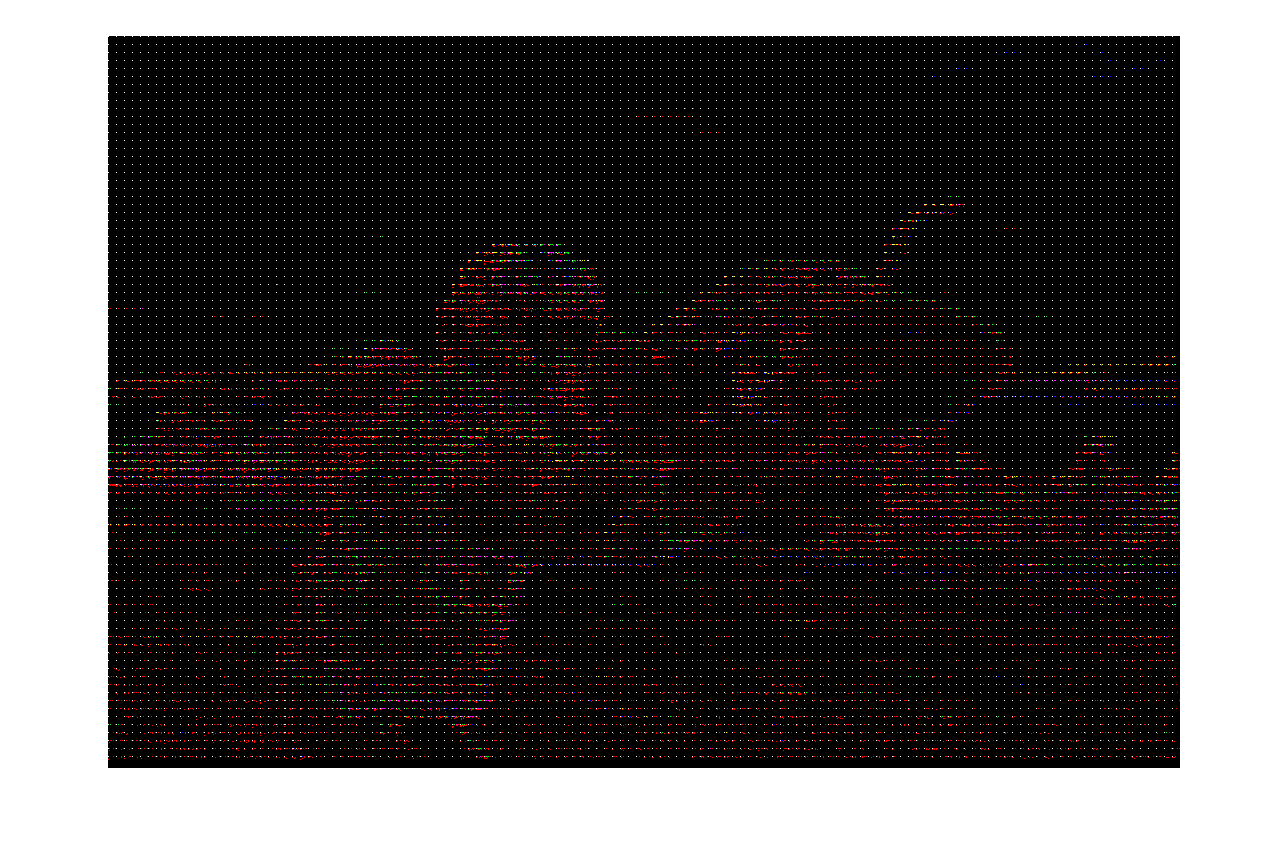

imshow(pilot_encode);


pilot_qua(1:8,41:48,:)

ans = ans(:,:,1) =

    55     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

    72     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,3) =

    58     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     

pilot_encode(1:8,41:48,:)

ans = ans(:,:,1) =

    55     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

    72     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,3) =

    58     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     



%for i=1:row/8
%    for j=1:col/8
%        for k=1:channel
%            inverse_downsample_pilot=pilot_dct(8*i-7:8*i,8*j-7:8*j,k);
%            pilot_YUV_recover(8*i-7:8*i,8*j-7:8*j,k)=idct2(inverse_downsample_pilot);
%        end
%    end
%end
%imshow(pilot_YUV_recover);